Zad 5 bo 1-4 mam na PC i wyślę dziś

### Zad 5

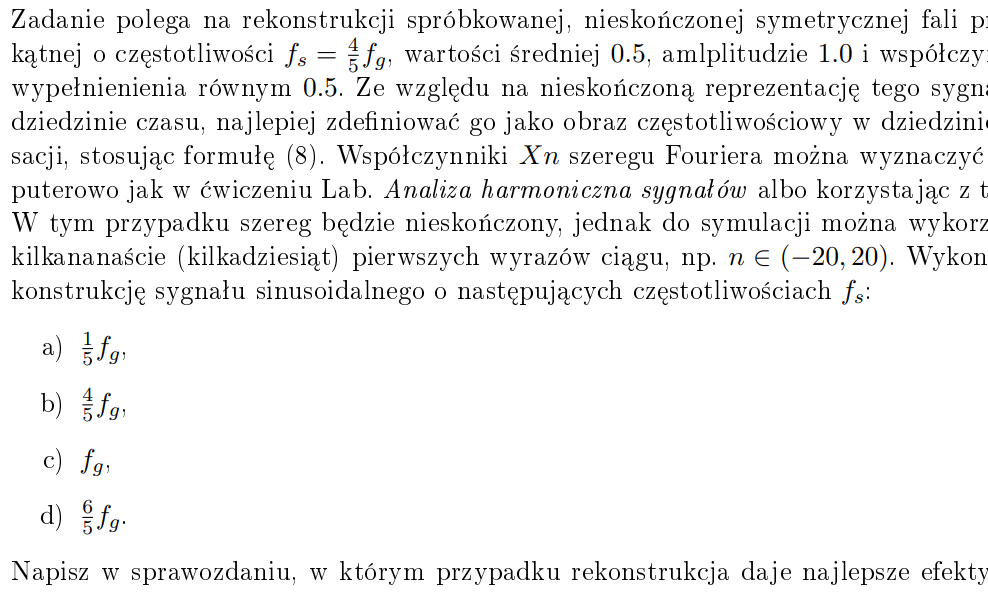

clear all; close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
s = 1/5; ws = s*wg;
Ts = 1/s/fg;

Ts = 0.0500

Skonstruowanie jednego okresu sygnału

xTT = rectangularPulse(-Ts/4, Ts/4, t);

$$xTT = \mathrm{rectangularPulse}\left(-\frac{1}{80},\frac{1}{80},t\right)$$

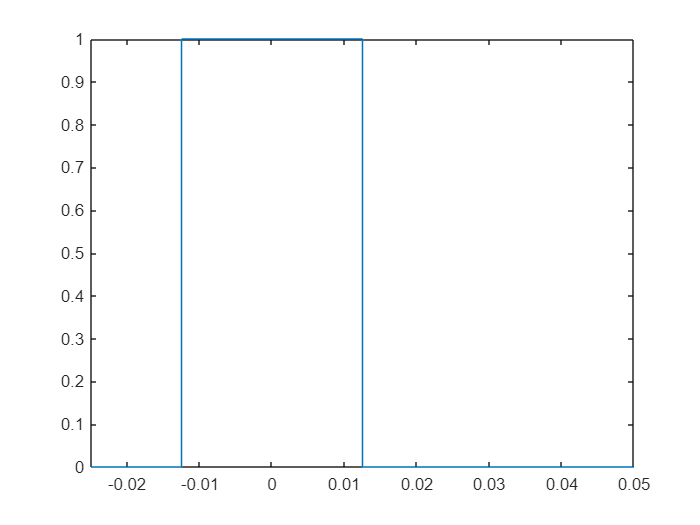

fplot(xTT, [-Ts/2, Ts]);

Wyznaczenie wspołczynników zespolonego szeregu Fouriera 

NT = 20;
ind = -NT : NT;
X = sym(0);
for n = ind
    Xn = (ws)*int(xTT*exp(-1i*ws*n*t),t, [-1/4*Ts, 3/4*Ts]);
    %Xn to współczynnik
    X = X + sym(Xn)*dirac(w-n*ws);
end

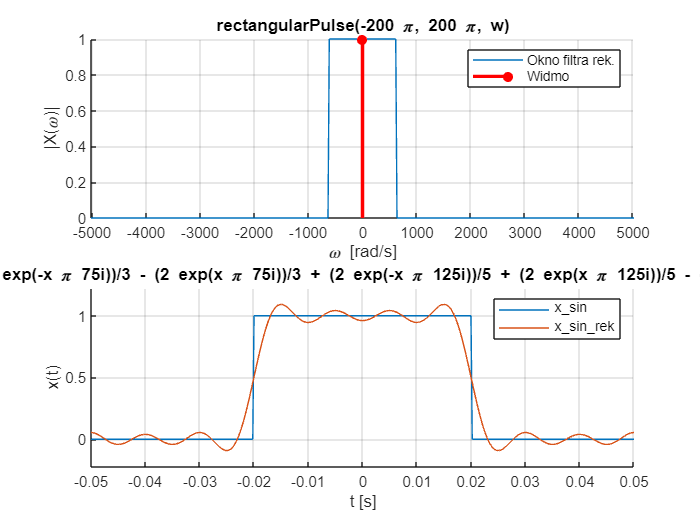

X_FT_sin = X;
x_sin = xTT;

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

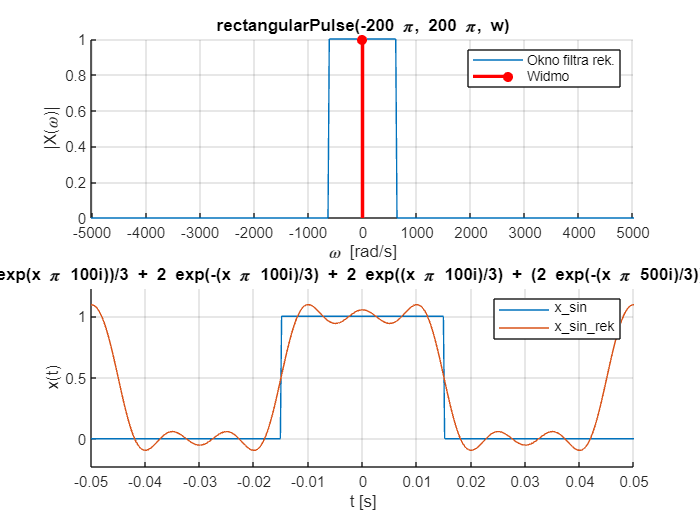

rectwave(1/6)

function [] = rectwave(s)

close all;
syms t x w K
fp = 200; fg = fp/2; %Hz
wp = 2*pi*fp; wg = 2*pi*fg;
ws = s*wg;
Ts = 1/s/fg;
xTT = rectangularPulse(-Ts/4, Ts/4, t);

NT = 20;
ind = -NT : NT;
X = sym(0);
for n = ind
    Xn = (ws)*int(xTT*exp(-1i*ws*n*t),t, [-1/4*Ts, 3/4*Ts]);
    %Xn to współczynnik
    X = X + sym(Xn)*dirac(w-n*ws);
end

X_FT_sin = X;
x_sin = xTT;

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

end